#     COVID-19 spread

## Data

breakdown = false;
if breakdown
    regione="Abruzzo";
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-regioni/dpc-covid19-ita-regioni.csv","./dati.csv") ;
else
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv","./dati.csv") ;
end


dati=readtable(data_location);
delete dati.csv

if breakdown
    dati = dati(dati.denominazione_regione==regione, :);
end
dati = dati(:,{'data','totale_casi'});
dati.data = datetime(dati.data,"Format","uuuu-MM-dd'T'HH:mm:ss");

disp(dati)

           data            totale_casi
    ___________________    ___________

    2020-02-24T18:00:00         229   
    2020-02-25T18:00:00         322   
    2020-02-26T18:00:00         400   
    2020-02-27T18:00:00         650   
    2020-02-28T18:00:00         888   
    2020-02-29T18:00:00        1128   
    2020-03-01T18:00:00        1694   
    2020-03-02T18:00:00        2036   
    2020-03-03T18:00:00        2502   
    2020-03-04T18:00:00        3089   
    2020-03-05T18:00:00        3858   
    2020-03-06T18:00:00        4636   
    2020-03-07T18:00:00        5883   
    2020-03-08T18:00:00        7375   
    2020-03-09T18:00:00        9172   
    2020-03-10T18:00:00       10149   
    2020-03-11T17:00:00       12462   
    2020-03-12T17:00:00       15113   
    2020-03-13T17:00:00       17660   
    2020-03-14T17:00:00       21157   
    2020-03-15T17:00:00       24747   
    2020-03-16T17:00:00       2798

confirmed_cases = dati.totale_casi;
day_num = datenum(dati.data - dati.data(1));
CURRENT = day_num(end);

## Data fitting

[linfit, lin_r] = fit(day_num, confirmed_cases, 'poly1');
[expfit, exp_r] = fit(day_num, confirmed_cases, 'exp1');
[logfit, log_r] = logisticFit(day_num, confirmed_cases);

## Plotting

### Linear fitting

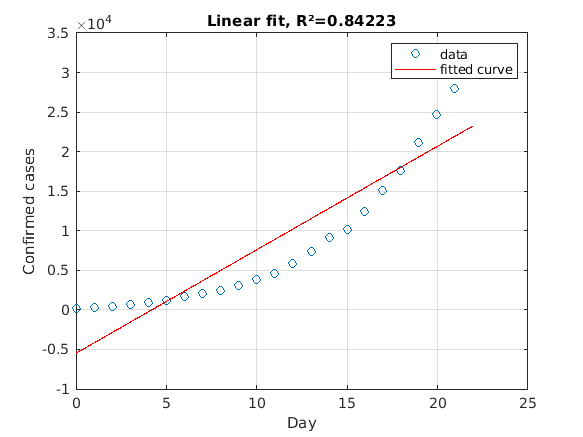

plot(linfit, day_num, confirmed_cases, "o")
grid on

title("Linear fit, R²="+lin_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")


disp(linfit.p1+" new cases each day.")

1308.7296 new cases each day.


disp("Predicted new cases for tomorrow: "+round(linfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: -6942


### Exponential fitting

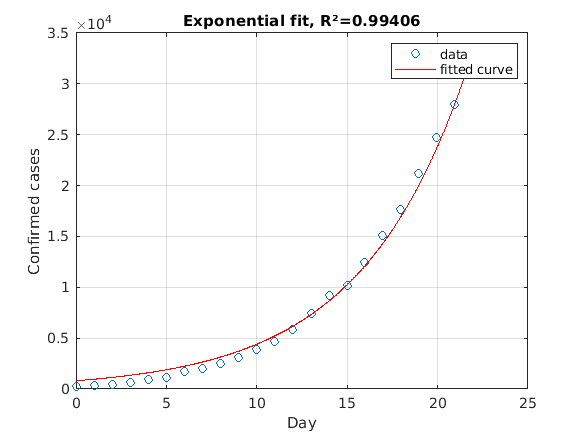

plot(expfit, day_num, confirmed_cases, "o")
grid on

title("Exponential fit, R²="+exp_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")


disp("+"+expfit.b*100+"% new confirmed cases each day")

+16.9018% new confirmed cases each day


disp("Predicted new cases for tomorrow: "+round(expfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 7862


## Logistic fitting

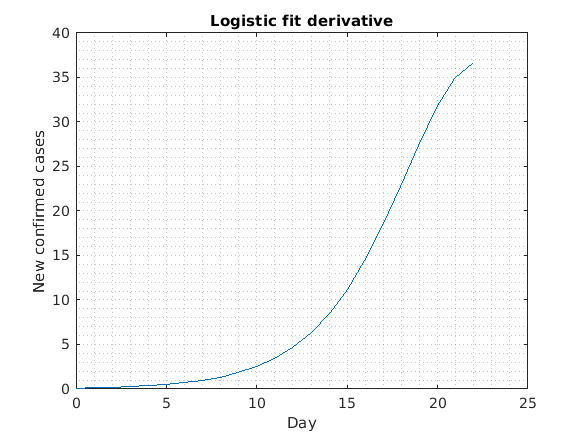

plot(logfit, day_num, confirmed_cases, "o")
grid on

title("Logistic fit, R²="+log_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
plot(day_num,differentiate(logfit, day_num));
grid minor

title("Logistic fit derivative")
ylabel("New confirmed cases")
xlabel("Day")


variation=round(predint(logfit,CURRENT+1,0.95)-confirmed_cases(end));
disp("Predicted new cases for tomorrow: "+round(logfit(CURRENT+1)-confirmed_cases(end)));

Predicted new cases for tomorrow: 18


disp("                                         95% confidence in range ["+variation(1) + " - "+ variation(2)+"]");

                                         95% confidence in range [2 - 34]


## Future projections

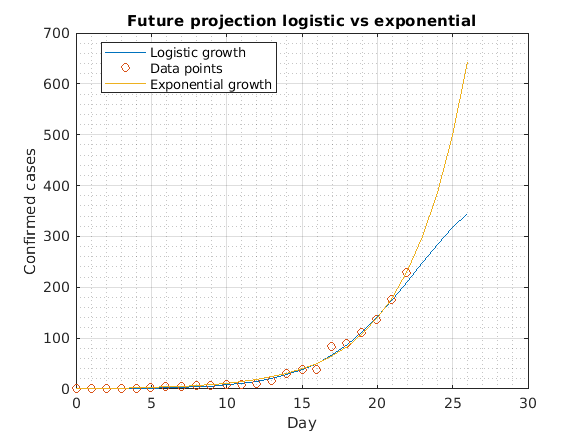

look_ahead_days = 5;
compare=true;
error_bars=false;

plot(0:(CURRENT+look_ahead_days),logfit(0:(CURRENT+look_ahead_days)))
hold on


grid on
grid minor
title("Future projection assuming logistic behaviour")
ylabel("Confirmed cases")
xlabel("Day")
scatter(day_num,confirmed_cases)

legend({'Logistic growth','Data points'}, "Location","best");

if compare
    plot(0:(CURRENT+look_ahead_days),expfit(0:(CURRENT+look_ahead_days)))
    title("Future projection logistic vs exponential")
    legend({'Logistic growth','Data points', 'Exponential growth'}, "Location","best");
end
if error_bars
    log_ci = predint(logfit,1:(CURRENT+look_ahead_days),0.95);
    plot(1:(CURRENT+look_ahead_days),log_ci,'LineWidth',0.001);
    legend({'Logistic growth','Data points','Lower bound','Upper bound'}, "Location","best");

end
hold off

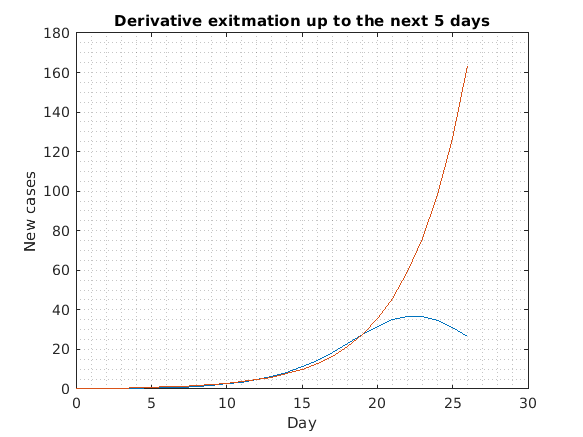

plot(0:(CURRENT+look_ahead_days),differentiate(logfit, 0:(CURRENT+look_ahead_days)));
grid minor

title("Derivative exitmation up to the next " + look_ahead_days+" days");
ylabel("New cases")
xlabel("Day")
if compare
    hold on
    plot(0:(CURRENT+look_ahead_days),differentiate(expfit, 0:(CURRENT+look_ahead_days)));
    hold off

end

## Comparison with past projections:

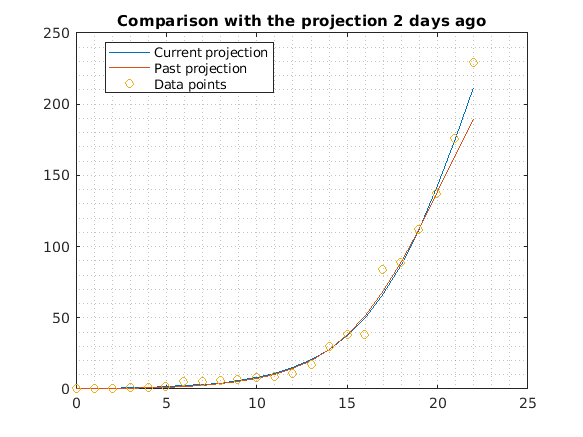

look_ahead_days = 1;
look_behind_days = 2;

model="Logistic";

reduced_day=day_num(1:(end-look_behind_days));
reduced_cases=confirmed_cases(1:(end-look_behind_days));

if model == "Logistic"
    model_current = logfit;
    model_past = logisticFit(reduced_day, reduced_cases );
else
    model_current = expfit;
    model_past = fit(reduced_day, reduced_cases, 'exp1');
end


plot(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
hold on
plot(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off

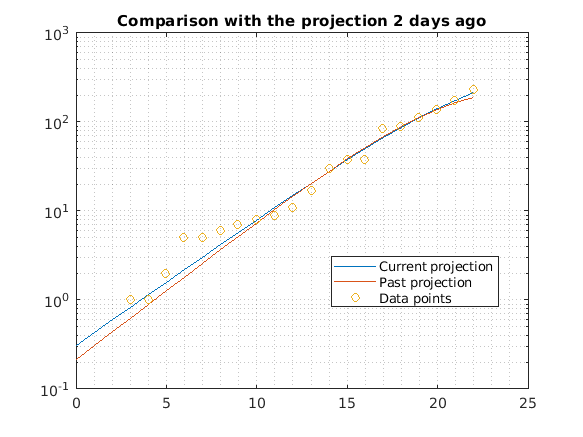


semilogy(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
hold on
semilogy(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off

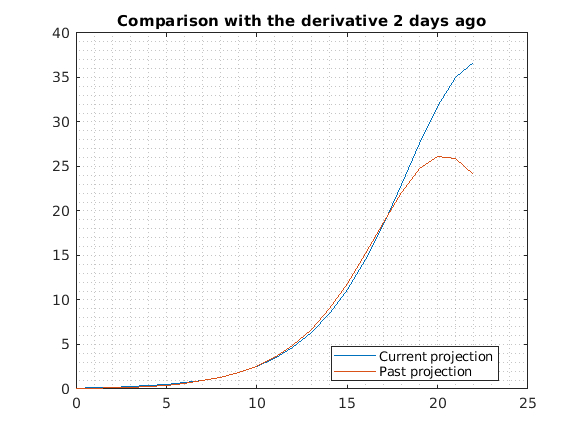


plot(0:(CURRENT+look_ahead_days),differentiate(model_current, 0:(CURRENT+look_ahead_days)));
hold on
plot(0:(CURRENT+look_ahead_days),differentiate(model_past, 0:(CURRENT+look_ahead_days)));
title("Comparison with the derivative "+look_behind_days+" days ago");
legend({'Current projection','Past projection'}, "Location","best");
grid minor
hold off